# Connecting Data Using Datastore

In this example will be looking at a large amount of vibrationmeasurement data to get started using the new large capabilities found in R2014b. A |datastore| is an object useful for reading collections of data that are too large to fit in memory. It is a repository for multiple files and folders with the same structure and formatting.

## Connecting the data

ds = datastore('Vibration_data\*','Type','Tabulartext','Delimiter','\t','ReadVariableNames',false);         
ds.VariableNames = {'Ch1','Ch2','Ch3','Ch4','Ch5','Ch6','Ch7','Ch8'};

#### Preview the data

a = preview(ds)

a = 8×8 table
     Ch1       Ch2       Ch3       Ch4       Ch5       Ch6       Ch7       Ch8  
    ______    ______    ______    ______    ______    ______    ______    ______

     0.083    -0.027     0.024    -0.095    -0.015    -0.288    -0.273    -0.007
    -0.037    -0.295    -0.002      -0.1    -0.117    -0.037    -0.078    -0.032
     -0.19    -0.027    -0.122    -0.051    -0.071    -0.298     0.081    -0.205
      -0.4    -0.051    -0.093    -0.063    -0.234     -0.11     0.034    -0.122
    -0.205     0.002    -0.083    -0.129    -0.315    -0.264    -0.115    -0.178
     0.044    -0.222    -0.007    -0.325    -0.234    -0.215    -0.166    -0.095
      -0.1    -0.225    -0.129    -0.137     0.017    -0.439    -

#### Select the variable of interest

If we are only interested in one variable, we can discard the rest

ds.SelectedVariableNames = 'Ch2';

#### Read the chunk

The default size is 20000. You can change the number by 'ReadSize' properties in datasote object. The value can be any positive integers. We can also read one file at a time by change the setting to 'file'.

ds.ReadSize = 'file';
testdata = read(ds);

## Visualizing and analyzing data

With the help of datastore, we can continuously read and analyze data. Once the recording approaches the end, we can see some harmonic frequencies appearing, indicating immediate failure.

#### Create a new figure

figure;
ax1 = nexttile; % first subplot
ax2 = nexttile; % second subplot
title(ax2,'Time series data')

#### Create an animation

h1 = animatedline('Color',[0 0.4470 0.7410]);
axis tight
startidx = 0;

#### Sampling frequency of data

Fs = 20479;

#### Calculate the PSD and count the peaks using 'findpeaks'

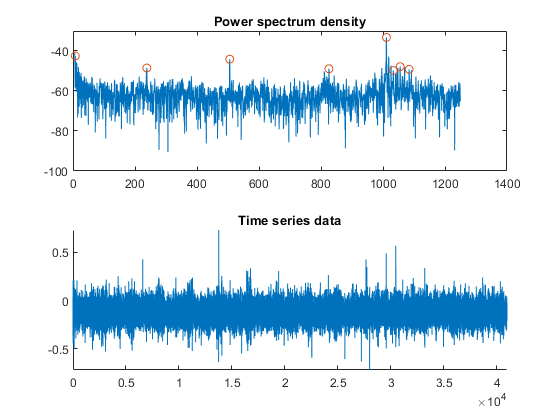

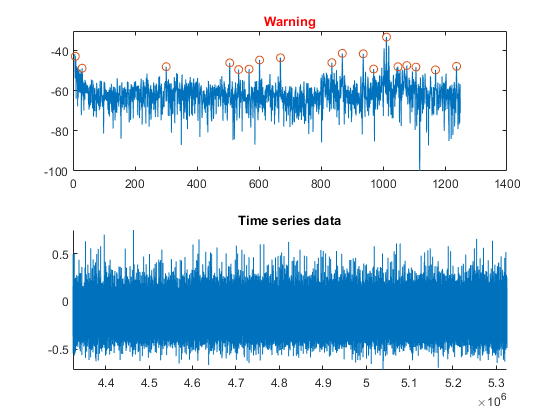

while hasdata(ds)

    % Read in Chunk
    dataChunk = read(ds);
    
    % add data to the animatedline -plot
    addpoints(h1,startidx:startidx+height(dataChunk)-1,dataChunk{:,1});
    drawnow
    
    % calculate PSD
    [P,f] = periodogram(table2array(dataChunk),[],[],Fs);
    plot(ax1,f(10:2000),10*log10(P(10:2000)))
    % Find peaks in data, specify criteria
    [pks,locs] = findpeaks(10*log10(P(10:2000)),f(10:2000),'MinPeakDistance',20,...
        'MinPeakHeight',-50,'MinPeakProminence',1);
    ylim(ax1,[-100, -30])
    hold(ax1,'on')
    plot(ax1,locs,pks,'o')
    hold(ax1,'off')
    
    % if we see addititional peaks in the PSD due to harmonic frequencies,
    % indicating possible failure, display a warning
    if numel(pks) > 11
        title(ax1,'Warning','color','red')
    else
        title(ax1,'Power spectrum density')
    end
    drawnow   

    % plot rolls after 1M data points, set axes to tight
    startidx = startidx + height(dataChunk);
    if startidx > 1e6
        axis auto tight
    end
end